clc; close all;
k = 4;
d = 30;
n = 5;
m = 1e5;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

Nruns = 100;
ps = 1;

JPTTime = zeros(ps, Nruns);

BWCost = zeros(2, Nruns);
BWTime = zeros(ps, Nruns);

UncoupledCost = zeros(2, Nruns);
UncoupledTime = zeros(ps, Nruns);

CoupledCost = zeros(2, Nruns);
CoupledTime = zeros(ps, Nruns);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);



for j = progress(1:Nruns)

    [T, Os, pi, ~, ~] = generateContinuousHMM(k, d, n, hmm_options);

    tic
    % [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, sampleArray(i));
    seq = generate_continuous_multivariate_hmm_sequence(T, Os, pi, m, 0);

    [~, mins, maxs] = NormalizeData(seq);
    [T, O_hists] = Discretize_cHMM(T, Os, mins, maxs, d);

    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end
    JPTTime(1, j) = toc;

    % Baum-Welch
   
    tic;
    [Mu,Cov,A,Pi]=BaumWelch(seq',k);

    T_hat = Stochasticize(A);
    [T_hat, O_hats] = Discretize_cHMM_BW(T_hat, Mu, Cov, mins, maxs, d);

    Pbest = MultivariatePermutationFitEmission(O_hists, O_hats);
    T_hat = Pbest * T_hat * Pbest';

    for ii = 1:n
        O_hats{ii} = O_hats{ii} * Pbest';
    end

    BWCost(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');  
    for ii = 1:n
        BWCost(2, j) = BWCost(2, j) + (1/n) * norm(O_hists{ii} - O_hats{ii}, 'fro') / norm(O_hists{ii}, 'fro');
    end

    BWTime(1, j) = toc;


    % Uncoupled CPD
    tic
    T_hat = zeros(k, k);
    for ii = 1:n
        [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
        O_hat = Stochasticize(B);
        T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
    
        Pbest = PermutationFit(T, T_hats{ii}, true);
        T_hats{ii} = Pbest * T_hats{ii} * Pbest';
        T_hat = T_hat + (1/n) * T_hats{ii};
    
        O_hats{ii} = O_hat * Pbest';
    end
    % T_hat

    UncoupledCost(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');
    for ii = 1:n
        UncoupledCost(2, j) = UncoupledCost(2, j) + (1/n) * norm(O_hists{ii} - O_hats{ii}, 'fro') / norm(O_hists{ii}, 'fro');
    end
    UncoupledTime(1, j) = toc;
    
    % Coupled CPD
    tic
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    CoupledCost(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');  
    for ii = 1:n
        CoupledCost(2, j) = CoupledCost(2, j) + (1/n) * norm(O_hists{ii} - O_hats{ii}, 'fro') / norm(O_hists{ii}, 'fro');
    end 
    CoupledTime(1, j) = toc;
end

Processing:  000%  |                                      | 0/100it [00:00:00<Inf:NaN:NaN, Inf it/s]


save("PerformanceTests/MethodComparison", "BWCost", "BWTime", "UncoupledCost", "UncoupledTime", "CoupledCost", "CoupledTime", "JPTTime");



load("PerformanceTests/MethodComparison");

[BWCostSTDTotal, BWCostMeanTotal] = std(sum(BWCost, 1), 0, 2)

BWCostSTDTotal = 0.4581

BWCostMeanTotal = 0.5104

[UncoupledCostSTDTotal, UncoupledCostMeanTotal] = std(sum(UncoupledCost, 1), 0, 2)

UncoupledCostSTDTotal = 0.2833

UncoupledCostMeanTotal = 0.2802

[CoupledCostSTDTotal, CoupledCostMeanTotal] = std(sum(CoupledCost, 1), 0, 2)

CoupledCostSTDTotal = 0.1617

CoupledCostMeanTotal = 0.1302





[BWCostSTD, BWCostMean] = std(BWCost, 0, 2)

BWCostSTD =     0.1869
    0.2749


BWCostMean =     0.2372
    0.2732


[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2)

UncoupledCostSTD =     0.1044
    0.1836


UncoupledCostMean =     0.0852
    0.1950


[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2)

CoupledCostSTD =     0.0306
    0.1407


CoupledCostMean =     0.0188
    0.1113



[BWTimeSTD, BWTimeMean] = std(BWTime, 0, 2)

BWTimeSTD = 17.1962

BWTimeMean = 148.1183

[UncoupledTimeSTD, UncoupledTimeMean] = std(UncoupledTime, 0, 2)

UncoupledTimeSTD = 2.2472

UncoupledTimeMean = 14.0460

[CoupledTimeSTD, CoupledTimeMean] = std(CoupledTime, 0, 2)

CoupledTimeSTD = 3.3375

CoupledTimeMean = 3.0826

[JPTTimeSTD, JPTTimeMean] = std(JPTTime, 0, 2)

JPTTimeSTD = 2.3387

JPTTimeMean = 16.9490

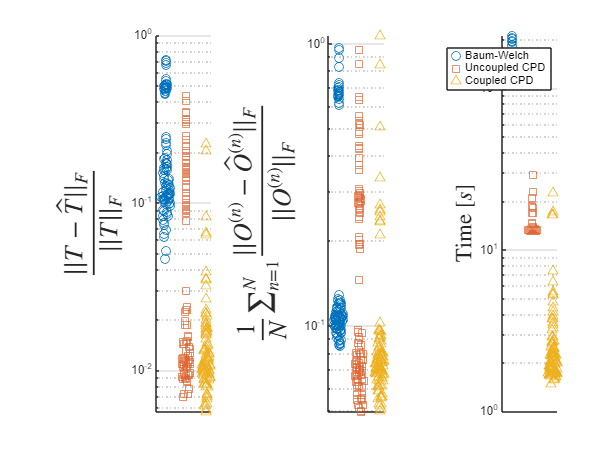



figure();

subplot(1, 3, 1)

swarmchart(ones(Nruns, 1), BWCost(1, :)', 'Marker','o'); hold on;
swarmchart(3 *ones(Nruns, 1), UncoupledCost(1, :)', 'Marker','s'); hold on;
swarmchart(5 *ones(Nruns, 1), CoupledCost(1, :)', 'Marker','^'); hold on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F}$", "Interpreter","latex",'FontSize',18,'FontWeight','bold')
% xticklabels(["Baum-Welch","Uncoupled CPD", "Coupled CPD"]) 
set(gca,'YScale','log', 'xtick',[]); grid on;

subplot(1, 3, 2)
swarmchart(ones(Nruns, 1), BWCost(2, :)', 'Marker','o'); hold on;
swarmchart(3 *ones(Nruns, 1), UncoupledCost(2, :)', 'Marker','s'); hold on;
swarmchart(5 *ones(Nruns, 1), CoupledCost(2, :)', 'Marker','^'); hold on;
ylabel("$\frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',18,'FontWeight','bold')
% xticklabels(["Baum-Welch","Uncoupled CPD", "Coupled CPD"]) 
set(gca,'YScale','log', 'xtick',[]); grid on;

subplot(1, 3, 3)
swarmchart(ones(Nruns, 1), BWTime', 'Marker','o'); hold on;
swarmchart(3 *ones(Nruns, 1), UncoupledTime', 'Marker','s'); hold on;
swarmchart(5 *ones(Nruns, 1), CoupledTime', 'Marker','^'); hold on;
ylabel("Time [$s$]", "Interpreter","latex",'FontSize',16,'FontWeight','bold')
legend(["Baum-Welch","Uncoupled CPD", "Coupled CPD"]) 
set(gca,'YScale','log', 'xtick',[]); grid on;